# Actividad 1: Velocidades Lineales y angulares

**Paola Rojas Domínguez** **A01737136**

En este reporte se explica el procedimiento hecho en MATLAB para el análisis cinemático de un robot planar de dos grados de libertad (2 GDL). Es decir, el robot está conformado por dos articulaciones rotacionales. El sistema de referencia fijo (Xo, Yo, Zo) se coloca en la base del robot, de tal forma que el eje Zo es perpendicular al plano de la imagen.

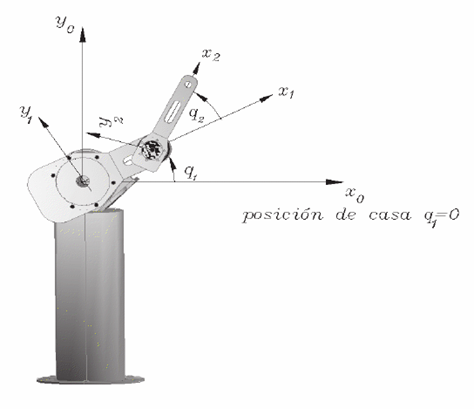

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores. Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

clear all
close all
clc

%Variables simbólicas
syms th1(t) l1 t th2(t) l2

Se configura el robot con dos articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP = [0 0];

Creamos el vector de coordenadas generalizadas

Q = [th1 th2];
disp('Coordenadas articulares'); pretty(Q);

Coordenadas articulares
(th1(t), th2(t))



Creamos el vector de velocidades articulares, la velocidad articular es la derivada temporal de las coordenadas articulares.

Qp = diff(Q, t);
disp('Velocidades articulares'); pretty(Qp); %Vector de las velocidades de las particulaciones

Velocidades articulares
/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot. Aquí, 2 GDL corresponden a las dos articulaciones rotacionales.

GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1

%Posición de la junta 1 respecto a 0
P(:,:,1) = [l1*cos(th1);
            l1*sin(th1); 
            0];

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1)  cos(th1) 0;
            0         0        1];

### Articulación 2

%Posición de la junta 1 respecto a 0
P(:,:,2) = [l2*cos(th2);
            l2*sin(th2); 
            0]; 

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0         0        1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL) = P(:,:,GDL); %****

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL) = R(:,:,GDL); %****

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str = num2str(i);
    %Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) =  simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));
    disp('    ');
    %Globales
    try
        T(:,:,i) = T(:,:,i-1) * A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    disp(strcat('Matriz de Rotación de la matriz global T', i_str));
    pretty(RO(:,:,i));
    disp('    ');
    disp(strcat('Vector de traslación de la matriz global T', i_str));
    pretty(PO(:,:,i));
    disp('    ');
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Rotación de la matriz global T1


/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



Vector de traslación de la matriz global T1


/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, #2 l2 + cos(th1(t)) l1 \
|                                    |
| #1,  #2, 0, #1 l2 + sin(th1(t)) l1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




Matriz de Rotación de la matriz global T2


/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



Vector de traslación de la matriz global T2


/ cos(th1(t) + th2(t)) l2 + cos(th1(t)) l1 \
|                                          |
| sin(th1(t) + th2(t)) l2 + sin(th1(t)) l1 |
|                                          |
\                     0                    /



## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición respecto a los ángulos articulares

%Derivadas parciales de x
Jv11 = functionalDerivative(PO(1,1,GDL), th1);
Jv12 = functionalDerivative(PO(1,1,GDL), th2);

%Derivadas parciales de y
Jv21 = functionalDerivative(PO(2,1,GDL), th1);
Jv22 = functionalDerivative(PO(2,1,GDL), th2);

%Derivadas parciales de z
Jv31 = functionalDerivative(PO(3,1,GDL), th1);
Jv32 = functionalDerivative(PO(3,1,GDL), th2);

%Creamos la matríz del Jacobiano lineal
jv_d = simplify([Jv11 Jv12;
                 Jv21 Jv22;
                 Jv31 Jv32]);

disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ - sin(th1(t) + th2(t)) l2 - sin(th1(t)) l1, -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  cos(th1(t) + th2(t)) l2 + cos(th1(t)) l1,   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



## Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k = 1:GDL
    if(RP(k)==0) %Casos de articulación rotacional
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k) = [0,0,1];
        end

    elseif(RP(k)==1) %Casos de articulación prismática
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1];
        end
        Jw_a(:,k) = [0,0,0];
    end
end

%Despliegue
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty(Jv_a);

Jacobiano lineal obtenido de forma analítica
/ - sin(th1(t) + th2(t)) l2 - sin(th1(t)) l1, -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  cos(th1(t) + th2(t)) l2 + cos(th1(t)) l1,   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



disp('Jacobiano angular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano angular obtenido de forma analítica
/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



## Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La Velocidad lineal describe el desplazamiento del efector.

V = simplify(Jv_a*Qp');
disp('Velocidad lineal obtenida mediante  el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante  el Jacobiano lineal
/   _________                               _________    \
|    d                                       d           |
| - -- th1(t) (#1 l2 + sin(th1(t)) l1) - l2 -- th2(t) #1 |
|   dt                                      dt           |
|                                                        |
|  _________                               _________     |
|   d                                       d            |
|  -- th1(t) (#2 l2 + cos(th1(t)) l1) + l2 -- th2(t) #2  |
|  dt                                      dt            |
|                                                        |
\                            0                           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




Mientras que la velocidad angular describe la rotación del efector.

W = simplify(Jw_a*Qp');
disp('Velocidad angular obtenida mediante  el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante  el Jacobiano angular
/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /



Este reporte ofrece un análisis teórico y práctico del código MATLAB para comprender la cinemática de un robot de 2 GDL, útil para simulaciones y aplicaciones en robótica.